# **Load case #3** Load on Fuselage - Landing gear load 

Two-point landing with front nose off (hence the need to consider a reaction at the main u/c, as well as sufficient tail loads to maintain landing attitude and pitching moment equilibrium). For this load case, consider the effect on the Bending Moment and Shear Force along the fuselage.

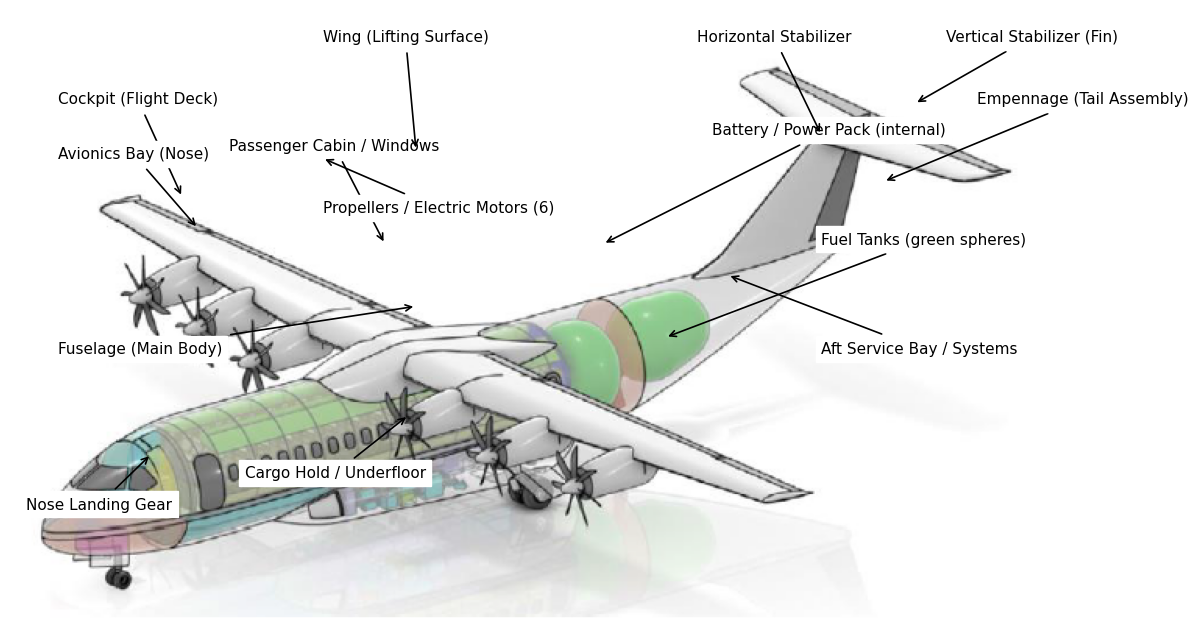

## ** Assumptions: **

- $n_{\textrm{landing}\;=\;\;} n_{\textrm{MTOW}}$ or we can assume a percentage (fuel burn) 

- Pitching angle is negligible ($|\theta |<<1\;\textrm{radians}$)

- Paint thickness is evenly spread throughout the airplane body

- Tank is a sphere, and modelled as a spherical load. It is assumed that although there the tank just touches a portion of the 

- Drag forces are not considered

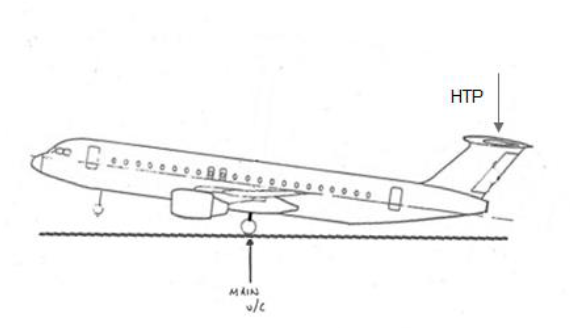

## Requirements:

- Shear force 

- Bending moment 

- Torque is not considered in this analysis as this load is largely symetrical 

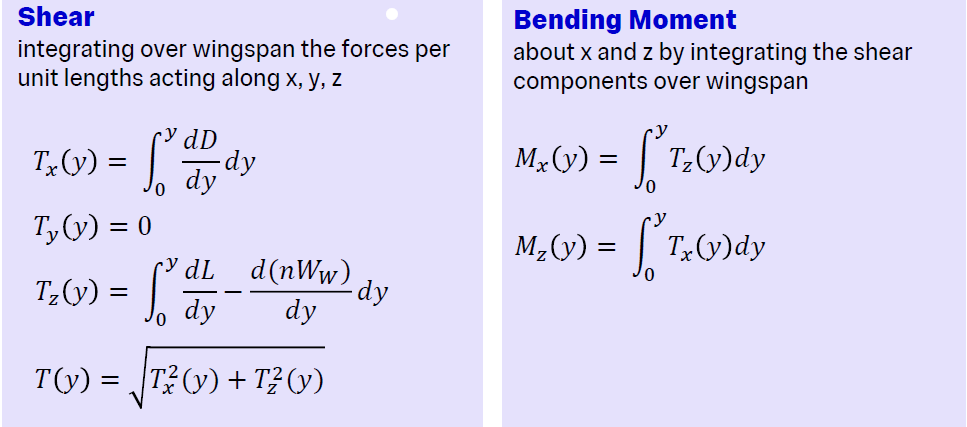

Types of loadings:  UDL (Uniformly distributed load), VDL (triangular), Parabolic, Spherical (semi-circle), PL (point load)

**Sign convention:**

- Upward forces  = + (positive)

- Downward forces = - (negative)

 Shear V(x) = sum of forces to the LEFT of x  (V(0)=0)

Bending M(x): M(0)=0, and dM/dx = V

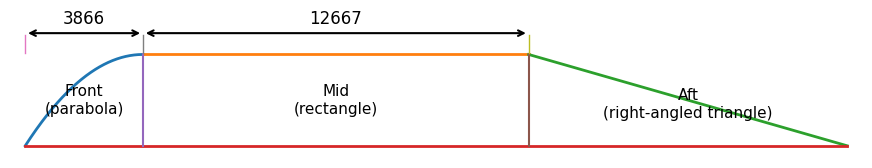

% Unknowns solved:
%   T (tail vertical load at x_HTP) and R_MG (main gear reaction at x_MG)
%   Nose-off means NO nose gear reaction.

clear; clc; close all;

The longitudinal inertia distribution along the fuselage, from the nose to the tail, is discretised by modelling the fuselage as an equivalent beam subjected to distributed and concentrated loads. These loads represent structural mass, aircraft subsystems, and localised components such as landing gear and empennage attachments. Variations in fuselage diameter are represented through piecewise distributed load functions. Fuel is modelled using spherical tanks of uniform density, while the paint layer is assumed to be uniformly distributed over the external surface.

g = 9.81;         % [m/s^2] acceleration due to gravity 

L     = 28.896;   % [m] fuselage beam length (0=nose)
x_MG  = 14.973;   % [m] main gear station (reaction unknown)
x_HTP = 26.123;   % [m] tail load application station (unknown T)

Npts = 4000;
x = linspace(0, L, Npts).';

% Unit is Newtons 'N'
valueUnit = "N";   % "N" 

% VDL shape choice:
%   "peak_at_start" -> intensity max at a, goes to 0 at b
%   "peak_at_end"   -> intensity 0 at a, max at b
VDL_mode = "peak_at_start";

% LOAD TABLE 
% Columns expected:
% Parameter, Type, Weight, DistanceFromNosex_0_, WeightDistribution_L_m_
%
% Notes:
% - For PL: WeightDistribution_L_m_ should be 0
% - For Spherical: WeightDistribution_L_m_ is interpreted as RADIUS [m]
% - If a PL row has Weight = NaN, it is treated as UNKNOWN tail load T at that x0

LoadTbl = table( ...
    ["Wing + Propulsion";
     "Empennage Point Load";
     "Empennage UDL";
     "Fuselage (front)";
     "Fuselage (mid)";
     "Fuselage (aft)";
     "Nose landing gear (mass item)";
     "Main landing gear (mass item)";
     "Paint (front)";
     "Paint (mid)";
     "Paint (aft)";
     "System (front and mid fuselage)";
     "Tank + fuel fwd";
     "Tank + fuel aft";
     "Payload"], ...
    categorical(["UDL"; "PL"; "UDL"; "Parabolic"; "UDL"; "VDL"; "PL"; "PL"; "Parabolic"; "UDL"; "VDL"; "UDL"; "Spherical"; "Spherical"; "UDL"]), ...
    [6.92E4; NaN; 6.98E3; 3.81E3; 2.49E4; 6.87E3; 3.91E3; 9.89E3; 236.9372; 1.55E3; 427.4935; 6.58E3; 9.20E3; 7.06E3; 7.69E4], ...
    [11.27; 26.0; 23.35; 0.0; 3.866; 16.533; 2.56; 14.973; 0.0; 3.866; 16.533; 0.0; 17.907; 20.705; 3.866], ...
    [2.85; 0.0; 5.546; 3.866; 12.667; 12.363; 0.0; 0.0; 3.866; 12.667; 12.363; 16.533; 1.374; 1.424; 12.667], ...
    'VariableNames', ["Parameter","Type","Weight","DistanceFromNosex_0_","WeightDistribution_L_m_"] );

disp(LoadTbl);

                Parameter                  Type       Weight    DistanceFromNosex_0_    WeightDistribution_L_m_
    _________________________________    _________    ______    ____________________    _______________________

    "Wing + Propulsion"                  UDL           69200            11.27                     2.85         
    "Empennage Point Load"               PL              NaN               26                        0         
    "Empennage UDL"                      UDL            6980            23.35                    5.546         
    "Fuselage (front)"                   Parabolic      3810                0                    3.866         
    "Fuselage (mid)"                     UDL           24900            3.866                   12.667         
    "Fuselage (aft)"                     VDL 

% CONVERT TO NEWTONS 
Value_N = nan(height(LoadTbl),1);

for i = 1:height(LoadTbl)
    if isnan(LoadTbl.Weight(i))
        Value_N(i) = NaN; % unknown (e.g., tail point load)
        continue
    end

    switch valueUnit
        case "N"
            Value_N(i) = LoadTbl.Weight(i);
        case "kN"
            Value_N(i) = 1e3 * LoadTbl.Weight(i);
        case "kg"
            Value_N(i) = LoadTbl.Weight(i) * g;
        otherwise
            error('valueUnit must be "N", "kN", or "kg".');
    end
end
LoadTbl.Value_N = Value_N;

% IDENTIFY UNKNOWN TAIL LOAD ROW (optional) 
% If there is a PL row with NaN weight, treat it as the unknown tail load T.
idxUnknownT = (LoadTbl.Type=="PL") & isnan(LoadTbl.Value_N);

if any(idxUnknownT)
    % If multiple, take the first
    k = find(idxUnknownT,1,'first');
    x_HTP = LoadTbl.DistanceFromNosex_0_(k);
    fprintf('\nDetected unknown tail PL at x_HTP = %.3f m (from table)\n', x_HTP);
end


Detected unknown tail PL at x_HTP = 26.000 m (from table)


%% -------------------- BUILD DISTRIBUTED LOAD INTENSITY w(x) --------------------
% w(x) is signed [N/m] (down negative)
w_dist = zeros(size(x));

% Helper to add a patch safely (clamped into [0,L])
addPatch = @(w,a,b) ( w .* ( (x>=a) & (x<=b) ) );

for i = 1:height(LoadTbl)
    typ = string(LoadTbl.Type(i));
    W   = LoadTbl.Value_N(i);     % [N] total magnitude (signed applied later)
    x0  = LoadTbl.DistanceFromNosex_0_(i);

    if isnan(W)
        % Unknown tail load handled later
        continue
    end

    switch typ
        case "UDL"
            Lp = LoadTbl.WeightDistribution_L_m_(i);
            if Lp<=0, error("UDL with non-positive length at row %d", i); end

            a = max(0, x0);
            b = min(L, x0 + Lp);

            w0 = -abs(W)/(b-a);   % [N/m], down negative
            w_dist = w_dist + addPatch(w0,a,b);


            case "VDL"
    Lp = LoadTbl.WeightDistribution_L_m_(i);
    if Lp<=0, error("VDL with non-positive length at row %d", i); end

    a = max(0, x0);
    b = min(L, x0 + Lp);
    Lc = (b-a);

    %  RULE 
    % If this is the FRONT segment (starts at nose and ends at ~3.866 m),
    % make it increase to the right (0 at nose -> peak at 3.866).
    isFrontVDL = (abs(a-0.0) < 1e-6) && (abs(Lc-3.866) < 1e-3);

    if isFrontVDL
        wA = 0;                 % 0 at nose
        wB = -2*abs(W)/Lc;      % peak (down negative) at x=3.866
    else
        % default: peak at start (your original)
        wA = -2*abs(W)/Lc;
        wB = 0;
    end

    mask = (x>=a) & (x<=b);
    s = (x(mask)-a)/Lc;         % 0..1
    w_dist(mask) = w_dist(mask) + (wA + (wB-wA).*s);

        case "Parabolic"
    % Front fuselage: radius starts at 0 at a and grows parabolically to D/2 at b.
    % r(s) ∝ s^2  => choose w(s) ∝ s^2 so load starts at 0 and increases to max at b.
    % (Total load is still normalized to equal W.)

    Lp = LoadTbl.WeightDistribution_L_m_(i);
    if Lp<=0, error("Parabolic with non-positive length at row %d", i); end

    a = max(0, x0);
    b = min(L, x0 + Lp);
    Lc = (b-a);

    mask = (x>=a) & (x<=b);
    s = (x(mask)-a)/Lc;     % 0..1

    shape = s.^2;           % starts at 0, increases parabolically to 1 at the end
    C = 1/3;                % integral_0^1 s^2 ds

    w0 = -abs(W)/(Lc*C);    % ensures total = W (down negative)
    w_dist(mask) = w_dist(mask) + w0.*shape;

        case "Spherical"
            % Treat as a semi-circular distributed load around center x0 with radius R:
            % w(s) = -w0*sqrt(1 - ((x-xc)/R)^2), for |x-xc|<=R
            % Total load = w0 * R * (pi/2)  => w0 = 2*abs(W)/(pi*R)
            R = LoadTbl.WeightDistribution_L_m_(i);
            if R<=0, error("Spherical with non-positive radius at row %d", i); end

            xc = x0;                % interpret DistanceFromNose as center
            a  = max(0, xc - R);
            b  = min(L, xc + R);

            w0 = 2*abs(W)/(pi*R);  % positive magnitude
            mask = (x>=a) & (x<=b);
            u = (x(mask)-xc)/R;    % in [-1,1]
            wsph = -w0 .* sqrt(max(0, 1 - u.^2)); % down negative
            w_dist(mask) = w_dist(mask) + wsph;

        case "PL"
            % Point loads handled later
            continue

        otherwise
            error("Unknown Type '%s' at row %d", typ, i);
    end
end

% POINT LOAD LIST (known) 
idxPL_known = (LoadTbl.Type=="PL") & ~isnan(LoadTbl.Value_N);
x_pl = LoadTbl.DistanceFromNosex_0_(idxPL_known);
P_pl = -abs(LoadTbl.Value_N(idxPL_known));  % signed down negative

%  KNOWN RESULTANTS FOR EQUILIBRIUM ABOUT MG
F_dist = trapz(x, w_dist);                       % [N]
M_MG_dist = trapz(x, w_dist .* (x - x_MG));      % [N*m]

F_pl = sum(P_pl);
M_MG_pl = sum(P_pl .* (x_pl - x_MG));

F_known = F_dist + F_pl;
M_MG_known = M_MG_dist + M_MG_pl;

% SOLVE UNKNOWNS: T @ HTP and R_MG 
T = - M_MG_known / (x_HTP - x_MG);     % [+up, -down]
R_MG = - (T + F_known);                % [+up]

% BUILD SHEAR + MOMENT 
% Distributed shear from w_dist:
V_dist = cumtrapz(x, w_dist);  % V(0)=0

% Add point loads and reactions as steps:
H = @(xx,a) double(xx >= a);
V = V_dist;
for k = 1:numel(P_pl)
    V = V + P_pl(k)*H(x, x_pl(k));
end
V = V + R_MG*H(x, x_MG) + T*H(x, x_HTP);

% Bending moment from shear:
M = cumtrapz(x, V);  % M(0)=0

% CHECKS
fprintf('\n--- Equilibrium check (signed) ---\n');


--- Equilibrium check (signed) ---


fprintf('F_known (dist + known PL)             = %.3f kN\n', F_known/1e3);

F_known (dist + known PL)             = -227.623 kN


fprintf('M_MG_known (about MG)                 = %.3f kN*m\n', M_MG_known/1e3);

M_MG_known (about MG)                 = 605.711 kN*m


fprintf('Tail load T @HTP                      = %.3f kN ( +up / -down )\n', T/1e3);

Tail load T @HTP                      = -54.930 kN ( +up / -down )


fprintf('Main gear reaction R_MG               = %.3f kN ( +up )\n', R_MG/1e3);

Main gear reaction R_MG               = 282.553 kN ( +up )


fprintf('Sum F (R_MG + T + known)              = %.3e N (should be ~0)\n', (R_MG + T + F_known));

Sum F (R_MG + T + known)              = 0.000e+00 N (should be ~0)


fprintf('Sum M about MG (T + known)            = %.3e N*m (should be ~0)\n', (T*(x_HTP-x_MG) + M_MG_known));

Sum M about MG (T + known)            = 0.000e+00 N*m (should be ~0)


fprintf('V(L)                                  = %.3e N (should be ~0)\n', V(end));

V(L)                                  = 1.615e-09 N (should be ~0)


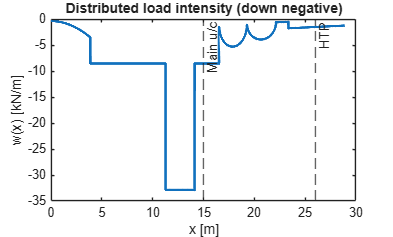

% Unknowns: ONLY T and R_MG
T    = - M_MG_known / (x_HTP - x_MG);
R_MG = - (T + F_known);


% PLOTS 
figure('Name','Distributed intensity w(x)');
plot(x, w_dist/1e3, 'LineWidth', 2); grid off;
xlabel('x [m]'); ylabel('w(x) [kN/m]');
title('Distributed load intensity (down negative)');
xline(x_MG,'--','Main u/c'); xline(x_HTP,'--','HTP'); yline(0,'--');

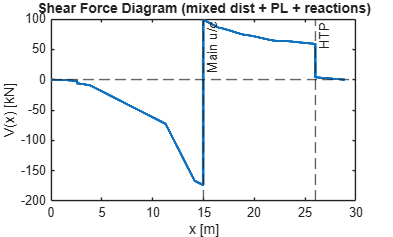

figure('Name','Shear Force Diagram V(x)');
plot(x, V/1e3, 'LineWidth', 2); grid off;
xlabel('x [m]'); ylabel('V(x) [kN]');
title('Shear Force Diagram (mixed dist + PL + reactions)');
xline(x_MG,'--','Main u/c'); xline(x_HTP,'--','HTP'); yline(0,'--');

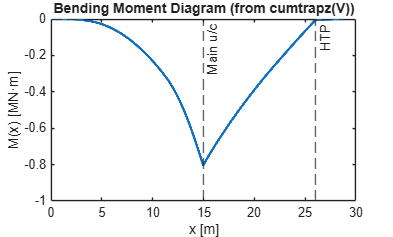

figure('Name','Bending Moment Diagram M(x)');
plot(x, M/1e6, 'LineWidth', 2); grid off;
xlabel('x [m]'); ylabel('M(x) [MN·m]');
title('Bending Moment Diagram (from cumtrapz(V))');
xline(x_MG,'--','Main u/c'); xline(x_HTP,'--','HTP'); yline(0,'--');

## LOADING VISUALS

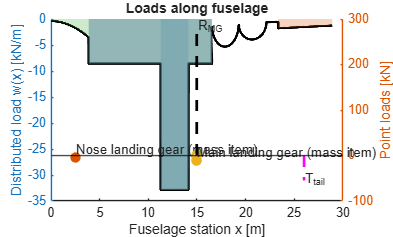

%% ----------------------------------------------------
% Separate load types (robust to string/cell/categorical)
idxUDL = strcmp(string(LoadTbl.Type),"UDL");
idxPL  = strcmp(string(LoadTbl.Type),"PL");

UDL = LoadTbl(idxUDL,:);
PL  = LoadTbl(idxPL,:);

% Colors
cUDL = lines(max(height(UDL),1));
cPL  = lines(max(height(PL),1));

%% ----------------------------------------------------
% FIGURE 1: Distributed loads + Point loads
figure('Name','Loads along fuselage');
hold on

yyaxis left
plot(x, w_dist/1e3,'k','LineWidth',2)
ylabel('Distributed load w(x) [kN/m]')

for k = 1:height(UDL)

    a = UDL.DistanceFromNosex_0_(k);
    L = UDL.WeightDistribution_L_m_(k);
    b = a + L;

    mask = (x>=a) & (x<=b);

    xs = x(mask)';
    ws = (w_dist(mask)/1e3)';

    if ~isempty(xs)

        patch([xs fliplr(xs)], ...
              [zeros(size(ws)) fliplr(ws)], ...
              cUDL(k,:), ...
              'FaceAlpha',0.25,...
              'EdgeColor','none');

    end

end

yyaxis right
ylabel('Point loads [kN]')

for k = 1:height(PL)

    xi = PL.DistanceFromNosex_0_(k);
    P  = -abs(PL.Value_N(k))/1e3;

    plot([xi xi],[0 P],'LineWidth',2,'Color',cPL(k,:))
    scatter(xi,P,60,cPL(k,:),'filled')

    if ~isempty(PL.Parameter(k))
        text(xi,P,string(PL.Parameter(k)), ...
            'VerticalAlignment','bottom',...
            'HorizontalAlignment','left');
    end

end

% Reactions
if exist('R_MG','var') && exist('x_MG','var')
    plot([x_MG x_MG],[0 R_MG/1e3],'k--','LineWidth',2)
    text(x_MG,R_MG/1e3,"R_{MG}")
end

if exist('T','var') && exist('x_HTP','var')
    plot([x_HTP x_HTP],[0 T/1e3],'m--','LineWidth',2)
    text(x_HTP,T/1e3,"T_{tail}")
end

xlabel('Fuselage station x [m]')
title('Loads along fuselage')

yline(0,'k-')

hold off

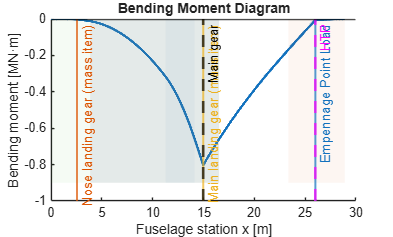



%% ----------------------------------------------------
% FIGURE 2: Bending Moment Diagram + Load Locations
figure('Name','Bending Moment Diagram');
hold on

plot(x,M/1e6,'LineWidth',2)

xlabel('Fuselage station x [m]')
ylabel('Bending moment [MN·m]')
title('Bending Moment Diagram')

yl = ylim;

% Distributed load regions
for k = 1:height(UDL)

    a = UDL.DistanceFromNosex_0_(k);
    L = UDL.WeightDistribution_L_m_(k);
    b = a + L;

    patch([a b b a], ...
          [yl(1) yl(1) yl(2) yl(2)], ...
          cUDL(k,:), ...
          'FaceAlpha',0.05,...
          'EdgeColor','none');

end

% Point loads
for k = 1:height(PL)

    xi = PL.DistanceFromNosex_0_(k);

    xline(xi,'Color',cPL(k,:), ...
        'LineWidth',1.5, ...
        'Label',string(PL.Parameter(k)));

end

% Key stations
if exist('x_MG','var')
    xline(x_MG,'k--','Main gear','LineWidth',2)
end

if exist('x_HTP','var')
    xline(x_HTP,'m--','HTP','LineWidth',2)
end

yline(0,'k-')

hold off